data_filename = './sample_data/vectornav_pitch45_5_17.csv';

% Our sample data has headers on the first line, so skip it
data = csvread(data_filename, 1);

% We'll use the time that the sample starts as each time
time = data(:, 1) * 10^(-9);
time = time - time(1);

% Using the first timestamp, calculate the sampling rate.
% With the configuration for the VectorNav, this will remain consistent.
sampling_rate = 1 / (time(2) - time(1));

yaw_pitch_roll_device = data(:, 4:6);
% IMU initialized using magnetometer.  Remove this bias.
%yaw_pitch_roll_device(:, 1) = yaw_pitch_roll_device(:, 1) - yaw_pitch_roll_device(1, 1);
orientation_device = quaternion(angle2quat(yaw_pitch_roll_device(:, 1), yaw_pitch_roll_device(:, 2), yaw_pitch_roll_device(:, 3)));
accel = data(:, 10:12);
gyro = data(:, 7:9);
mag = data(:, 19:21) / 100;

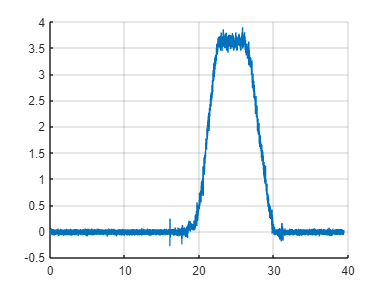

clf;
hold on;
plot(time, accel(:, 1));
grid on;
hold off;

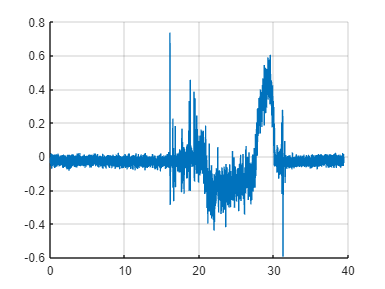

clf;
hold on;
plot(time, accel(:, 2));
grid on;
hold off;

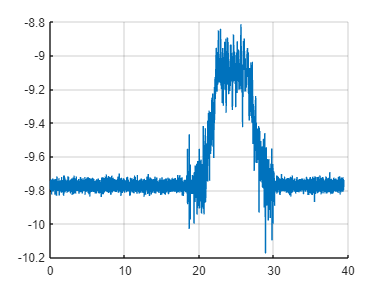

clf;
hold on;
plot(time, accel(:, 3));
grid on;
hold off;

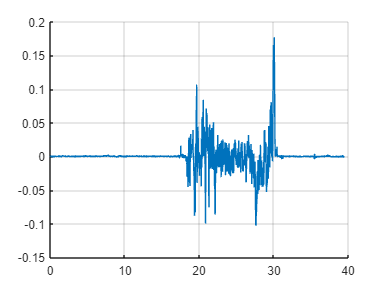

clf;
hold on;
plot(time, gyro(:, 1));
grid on;
hold off;

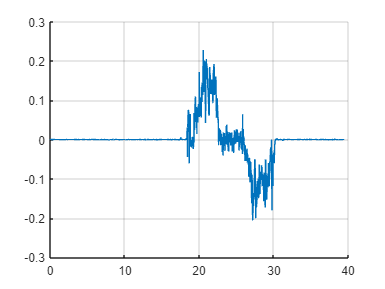

clf;
hold on;
plot(time, gyro(:, 2));
grid on;
hold off;

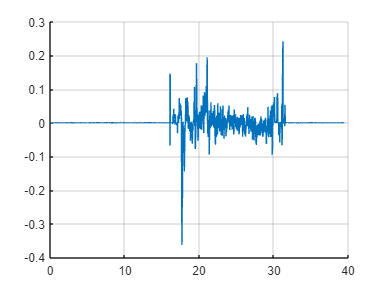

clf;
hold on;
plot(time, gyro(:, 3));
grid on;
hold off;

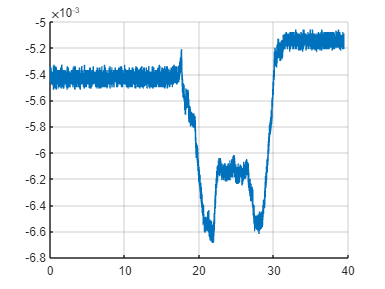

clf;
hold on;
plot(time, mag(:, 1));
grid on;
hold off;

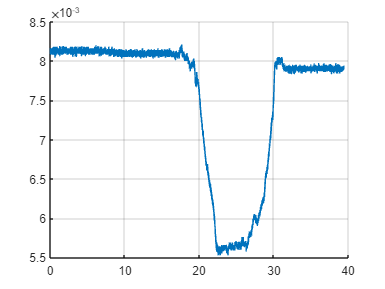

clf;
hold on;
plot(time, mag(:, 2));
grid on;
hold off;

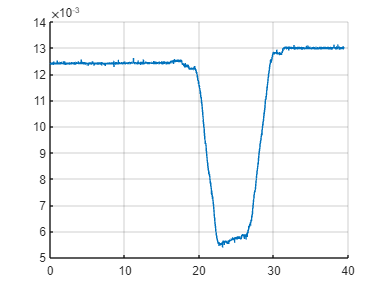

clf;
hold on;
plot(time, mag(:, 3));
grid on;
hold off;